# `DEMO_01:`    4-bar linkage analysis** - **`kinematics`

Let's analyze the kinematics of a 4bar linkage - see Figure_01 below.  We'll refer to the system **input** as $\theta$ and the system **output** as $\phi$.  If the machine allows the system input $\theta$ to rotate a full 360 degrees then we refer to the input link $L_1$ as a CRANK.  If the system output $\phi$ can only be rotated through a limited range of angles, then we refer to the output link $L_3$ as a ROCKER.

**Figure 01:  the 4bar linkage**

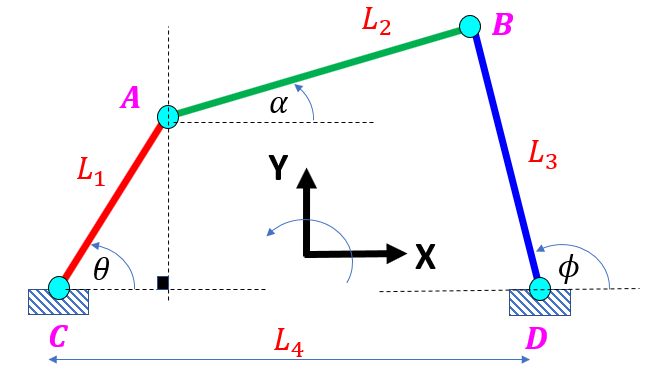

**REFs:**

- [https://en.wikipedia.org/wiki/Four-bar_linkage](https://en.wikipedia.org/wiki/Four-bar_linkage) 

- "A unified input-output analysis of a four bar linkags" - S.Bai, J.Angeles

- [https://www2.clarku.edu/faculty/djoyce/trig/identities.html](https://www2.clarku.edu/faculty/djoyce/trig/identities.html) 

 An alternate kinematics analysis is performed in the file <`DEMO_01b_bh_4bar_analysis_kinematics.mlx`> and it seems to be more "robust" than the approach which we will comment on here

`Bradley Horton : 24-Jul-2019, bhorton@mathworks.com`

## Define the symbolic geometry parameters:

syms L_1   L_2  L_3  L_4  theta phi

Let's define the relationships describing horizontal distances:

- 
$$L_4 \;\;=\;\;L_1 \ldotp \cos \left(\theta \right)\;+\;\;L_2 \ldotp \cos \left(\alpha \right)\;+\;\;L_3 \ldotp \cos \left(\pi -\phi \right)$$


- 
$$L_4 \;\;=\;\;L_1 \ldotp \cos \left(\theta \right)\;+\;\;L_2 \ldotp \cos \left(\alpha \right)-\;\;L_3 \ldotp \cos \left(\phi \right)$$


So we see that:

- $\;L_2 \ldotp \cos \left(\alpha \right)\;\;=L_4 \;-\;\;L_1 \ldotp \cos \left(\theta \right)\;+\;\;\;L_3 \ldotp \cos \left(\phi \right)$  ` .....    EQ_1`

And similarly the vertical distance:

- 
$$L_1 \ldotp \sin \left(\theta \right)\;\;+\;\;L_2 \ldotp \sin \left(\alpha \right)\;\;=\;\;\;\;L_3 \ldotp \sin \left(\pi -\phi \right)$$


- 
$$L_1 \ldotp \sin \left(\theta \right)\;\;+\;\;L_2 \ldotp \sin \left(\alpha \right)\;\;=\;\;\;\;L_3 \ldotp \sin \left(\phi \right)$$


So we see that:

- $L_2 \ldotp \sin \left(\alpha \right)\;\;=\;\;\;\;L_3 \ldotp \sin \left(\phi \right)\;\;-\;\;L_1 \ldotp \sin \left(\theta \right)\;$`.....    EQ_2`

So let's square `EQ_1` and `EQ_2` and add them together

EQ_C =     L_2^2 == (L_4 - L_1*cos(theta) + L_3*cos(phi))^2  +  (L_3*sin(phi) - L_1*sin(theta))^2

$$EQ\_C = {L_{2}}^{2}={\left(L_{4}+L_{3}\,\cos\left(\varphi \right)-L_{1}\,\cos\left(\theta \right)\right)}^{2}+{\left(L_{3}\,\sin\left(\varphi \right)-L_{1}\,\sin\left(\theta \right)\right)}^{2}$$

## Looking for $\phi =f\left(\theta \right)$

`EQ_C` is pretty ugly .... but we can use it to find a functional relationship between $\phi$and $\theta$, ie:  $\phi =f\left(\theta \right)$.  A trick that engineers have found (eg: REF_02, 03), is the following. Let:

- 
$$z=\tan \left(\frac{\phi }{2}\right)\;\Longrightarrow \;\;\;\;\sin \left(\phi \right)=\frac{2z}{1+z^2 }\;\;\;\;\;\;\textrm{and}\;\;\;\;\;\;\;\cos \left(\phi \right)=\frac{1-z^2 }{1+z^2 }\;\;\;\;\;\;$$


This transformation allows us to convert **EQ_C** into a quadratic.  So let's substitute this into `EQ_C` and see what pops out:

syms z
sp   =   (2*z)   / (1 + z^2);
cp   = (1 - z^2) / (1 + z^2);
EQ_C = subs(EQ_C, {sin(phi), cos(phi)}, {sp, cp})

$$EQ\_C = {L_{2}}^{2}={\left(L_{1}\,\sin\left(\theta \right)-\frac{2\,L_{3}\,z}{z^{2}+1}\right)}^{2}+{\left(L_{1}\,\cos\left(\theta \right)-L_{4}+\frac{L_{3}\,\left(z^{2}-1\right)}{z^{2}+1}\right)}^{2}$$

Note that if we make the assumptin that ($\left.z^2 +1\not= 0\right)$, then `EQ_C` is just a quadratic in terms of $z$

simplify( expand(EQ_C) )  % you see that it becomes a quadratic with a condition

$$ans = \begin{array}{l} \sigma_{1}\,\left({L_{1}}^{2}\,z^{2}+{L_{1}}^{2}+2\,\cos\left(\theta \right)\,L_{1}\,L_{3}\,z^{2}+{L_{3}}^{2}\,z^{2}+{L_{3}}^{2}+2\,L_{3}\,L_{4}+{L_{4}}^{2}\,z^{2}+{L_{4}}^{2}\right)=\sigma_{1}\,\left({L_{2}}^{2}+{L_{2}}^{2}\,z^{2}+2\,L_{1}\,L_{3}\,\cos\left(\theta \right)+2\,L_{1}\,L_{4}\,\cos\left(\theta \right)+2\,L_{3}\,L_{4}\,z^{2}+4\,L_{1}\,L_{3}\,z\,\sin\left(\theta \right)+2\,L_{1}\,L_{4}\,z^{2}\,\cos\left(\theta \right)\right)\wedge z\neq -\mathrm{i}\wedge z\neq \mathrm{i}\\ \mathrm{where}\\ \sigma_{1}={\left(z^{2}+1\right)}^{2} \end{array}$$

And we can of course solve for the roots of this quadratic - remember that IFFF we know $z$ then we can compute $\phi$, via:

- 
$$z_i =\tan \left(\frac{\phi_i }{2}\right)\;\;\Longrightarrow \;\;\;\;\phi_i =\;2\ldotp \arctan \left(z_i \right)$$


the_z = solve(EQ_C, z);
the_z = simplify(the_z)

$$the\_z = \begin{array}{l} \left(\begin{array}{c} \frac{\sigma_{1}+2\,L_{1}\,L_{3}\,\sin\left(\theta \right)}{\sigma_{2}}\\ -\frac{\sigma_{1}-2\,L_{1}\,L_{3}\,\sin\left(\theta \right)}{\sigma_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\left(-{L_{1}}^{2}+2\,\cos\left(\theta \right)\,L_{1}\,L_{4}+{L_{2}}^{2}+2\,L_{2}\,L_{3}+{L_{3}}^{2}-{L_{4}}^{2}\right)\,\left({L_{1}}^{2}-2\,\cos\left(\theta \right)\,L_{1}\,L_{4}-{L_{2}}^{2}+2\,L_{2}\,L_{3}-{L_{3}}^{2}+{L_{4}}^{2}\right)}\\ \sigma_{2}={L_{1}}^{2}+2\,\cos\left(\theta \right)\,L_{1}\,L_{3}-2\,\cos\left(\theta \right)\,L_{1}\,L_{4}-{L_{2}}^{2}+{L_{3}}^{2}-2\,L_{3}\,L_{4}+{L_{4}}^{2} \end{array}$$

## Do we have a VALID machine ?

So there are 2 roots, say $z_1$ and $z_2$.   NOTE the following about these roots:

- **THE SQUARE ROOT:**  It's entirely possible that a specific combination of $L_1 ,L_2 ,L_3 ,L_4 ,\theta \;$ could result in  COMPLEX values for $z_1$ and $z_2$.  This indicates that the machine simply canNOT be placed in that pose (ie: you've specified a value of $\theta$ which the machine can NOT be configured to).  Similarly, perhaps the combination of the link lengths does NOT allow the machine to be "connected", eg:  $L_1 =0\ldotp 1\;\;,L_2 =1,L_3 =2,\;L_4 =100$

- **THE DENOMINATOR:**  For some combinations of $L_1 ,L_2 ,L_3 ,L_4 ,\theta$ it's possible that the denominator (call it **D**) could be ZERO.  ***SPOILER alert: ***perhaps this means that our problem is no longer represented by a "quadratic" equation.

As an ***example ***of a potential mathematical singularity, consider the denominator of $z_1$:

[N, D] = numden(the_z(1));
D = simplify(D)

$$D = {L_{1}}^{2}+2\,\cos\left(\theta \right)\,L_{1}\,L_{3}-2\,\cos\left(\theta \right)\,L_{1}\,L_{4}-{L_{2}}^{2}+{L_{3}}^{2}-2\,L_{3}\,L_{4}+{L_{4}}^{2}$$

For the case where **D=0**, consider the ***special*** case of interest when $L_3 =L_4$, and this leads to:

-         
$$D=0=\;L_1^2 \;\;+\;\;-\;L_2^2 \;+\;L_3^2 \;-2\ldotp L_3 \ldotp L_3 +\;L_3^2$$


-         
$$D=0=\;L_1^2 \;\;+\;\;-\;L_2^2 \;$$


-            
$$L_1 =L_2$$


ie:

subs(D,[L_3],[L_4])

$$ans = {L_{1}}^{2}-{L_{2}}^{2}$$

AND another configuration that results in $D=0$, is:    $L_1 =L_2 {\;=\;L}_3 =L_4$.  

  For a more detailed exploration of these mathematical singularities see the script file:

- `bh_explore_Singularities_for_a_machine.mlx`

- `bh_explore_Singularities.mlx`

 An alternate kinematics analysis is performed in the file <`DEMO_01b_bh_4bar_analysis_kinematics.mlx`> and it seems to be more "robust".

## Assume we have a VALID machine pose:

Assuming that we do have a combination of $L_1 ,L_2 ,L_3 ,L_4 ,\theta \;$ that produces REAL values for $z_1$ and $z_2$ then we can compute the REAL value for $\phi \;$.  For these roots, we can write:

- 
$$z_i =\tan \left(\frac{\phi_i }{2}\right)\;\;\Longrightarrow \;\;\;\;\phi_i =\;2\ldotp \arctan \left(z_i \right)$$


In practice though we'll utilise the "4-quadrant" inverse `tan` function, ie:

-    $\phi =2\ldotp \textrm{atan2}\left(Y,X\right)$  where  $\frac{\phi }{2}\;\;\epsilon \;\left\lbrack -\pi ,\;\pi \;\right\rbrack$. 

### Computing $\phi_1 \left(\theta \right)$:

 For example here's how we'd compute $\phi_1 \left(\theta \;\right)$

[N,D] = numden( the_z(1) )

$$N = \sqrt{\left(-{L_{1}}^{2}+2\,\cos\left(\theta \right)\,L_{1}\,L_{4}+{L_{2}}^{2}+2\,L_{2}\,L_{3}+{L_{3}}^{2}-{L_{4}}^{2}\right)\,\left({L_{1}}^{2}-2\,\cos\left(\theta \right)\,L_{1}\,L_{4}-{L_{2}}^{2}+2\,L_{2}\,L_{3}-{L_{3}}^{2}+{L_{4}}^{2}\right)}+2\,L_{1}\,L_{3}\,\sin\left(\theta \right)$$

$$D = {L_{1}}^{2}+2\,\cos\left(\theta \right)\,L_{1}\,L_{3}-2\,\cos\left(\theta \right)\,L_{1}\,L_{4}-{L_{2}}^{2}+{L_{3}}^{2}-2\,L_{3}\,L_{4}+{L_{4}}^{2}$$

phi_sol_1 = 2*atan2( N, D  );

### Computing $\phi_2 \left(\theta \right)$:

And similarly for $\phi_2 \left(\theta \right)$:

[N,D] = numden( the_z(2) );
phi_sol_2 = 2*atan2( N, D  )

$$phi\_sol\_2 = \begin{array}{l} 2\,\text{atan2}\left(2\,L_{1}\,L_{3}\,\sin\left(\theta \right)-\sqrt{\left(-{L_{1}}^{2}+\sigma_{1}+{L_{2}}^{2}+2\,L_{2}\,L_{3}+{L_{3}}^{2}-{L_{4}}^{2}\right)\,\left({L_{1}}^{2}-\sigma_{1}-{L_{2}}^{2}+2\,L_{2}\,L_{3}-{L_{3}}^{2}+{L_{4}}^{2}\right)},{L_{1}}^{2}+2\,\cos\left(\theta \right)\,L_{1}\,L_{3}-\sigma_{1}-{L_{2}}^{2}+{L_{3}}^{2}-2\,L_{3}\,L_{4}+{L_{4}}^{2}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\cos\left(\theta \right)\,L_{1}\,L_{4} \end{array}$$

## Looking for $\alpha \;=f\left(\theta ,\phi \right)$

Next let's look for a relationship for $\alpha$ of the form $\alpha =f\left(\theta ,\phi \;\right)$.  Recall `EQ_1` and `EQ_2`:

- $\;\;L_2 \ldotp \sin \left(\alpha \right)\;\;=\;\;\;\;L_3 \ldotp \sin \left(\phi \right)\;\;-\;\;L_1 \ldotp \sin \left(\theta \right)\;$`.....    EQ_2`

- $\;\;L_2 \ldotp \cos \left(\alpha \right)\;\;=\;\;\;\;L_4 \;-\;\;L_1 \ldotp \cos \left(\theta \right)\;+\;\;\;L_3 \ldotp \cos \left(\phi \right)$  ` .....    EQ_1`

So we conclude that:

- 
$$\tan \left(\alpha \;\right)\;\;=\;\;\frac{L_3 \ldotp \sin \left(\phi \right)\;\;-\;\;L_1 \ldotp \sin \left(\theta \right)}{L_4 \;-\;\;L_1 \ldotp \cos \left(\theta \right)\;+\;\;\;L_3 \ldotp \cos \left(\phi \right)}\;\;\;$$


And again using the 4 quadrant inverse `tan` function we can write:

- 
$$\alpha \left(\;\theta ,\;\phi \right)\;=\textrm{atan2}\left(L_3 \ldotp \sin \left(\phi \right)-L_1 \ldotp \sin \left(\theta \right),\;\;\;\;\;{\;L}_4 \;-L_1 \ldotp \cos \left(\theta \right)\;+\;L_3 \ldotp \cos \left(\phi \right)\right)$$


So our expression for $\alpha \left(\;\theta ,\;\phi \right)$ is:

- NOTE:  their will be 2 solutions for $\alpha$, ie:  $\alpha \left(\;\theta ,\phi_1 \right)$  and  $\alpha \left(\;\theta ,\phi_2 \right)$

alpha_sol = atan2(  (L_3*sin(phi) - L_1*sin(theta))      , ...
                    (L_4 - L_1*cos(theta) + L_3*cos(phi))    );  

## Create MATLAB functions - part 1

Let's convert these expressions for $z,\;\phi ,\alpha \;$into MATLAB functions, ie:

- 
$$z\left(L_1 ,L_2 ,L_3 ,L_4 ,\;\theta \right)$$


- 
$$\phi \left(L_1 ,L_2 ,L_3 ,L_4 ,\;\theta \right)$$


- 
$$\alpha \left(L_1 ,L_2 ,L_3 ,L_4 ,\;\theta ,\;\phi \right)$$


We'll use these kinematic relationships often.  Let's store these functional relationships into the following MATLAB *.m function files:

- `bh_z_func.m`

- `bh_phi_1_func.m`

- `bh_phi_2_func.m`

- `bh_alpha_func.m`

The following local subfunction uses the `matlabFunction` function to convert the symbolic expressions into reusable MATLAB functions

LOC_create_MATLAB_functions(the_z, phi_sol_1, phi_sol_2, alpha_sol)

## Create MATLAB functions - part 2

So what do these functions look like ? 

THE_FILE_TO_LOOK_AT = "bh_z_func.m";
dbtype(THE_FILE_TO_LOOK_AT)


1     function [the_z,the_num,the_den] = bh_z_func(L_1,L_2,L_3,L_4,theta)
2     %BH_Z_FUNC
3     %    [THE_Z,THE_NUM,THE_DEN] = BH_Z_FUNC(L_1,L_2,L_3,L_4,THETA)
4     
5     %    This function was generated by the Symbolic Math Toolbox version 8.3.
6     %    30-Sep-2019 08:28:02
7     
8     t2 = cos(theta);
9     t3 = sin(theta);
10    t4 = L_1.^2;
11    t5 = L_2.^2;
12    t6 = L_3.^2;
13    t7 = L_4.^2;
14    t8 = L_2.*L_3.*2.0;
15    t9 = L_3.*L_4.*2.0;
16    t10 = -t9;
17    t11 = -t4;
18    t12 = -t5;
19    t13 = -t6;
20    t14 = -t7;
21    t15 = L_1.*L_3.*t2.*2.0;
22    t16 = L_1.*L_4.*t2.*2.0;
23    t17 = L_1.*L_3.*t3.*2.0;
24    t18 = -t16;
25    t19 = t5+t6+t8+t11+t14+t16;
26    t20 = t4+t7+t8+t12+t13+t18;
27    t21 = t4+t6+t7+t10+t12+t15+t18;
28    t22 = 1.0./t21;
29    t23 = t19.*t20;
30    t24 = sqrt(t23);
31    t25 = t17+t24;
32    the_z = [t22.*t25;t22.*(t17-t24)];
33    if nargout > 1
34        the_num = [t25;t17-t24];
35    end
36    if nargout > 2
37        the_den =

## Explore the angular relationships - a VALID machine

Let's use these functions to explore a particular machine:  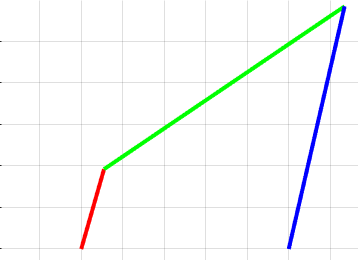

clear my
my.L1 = 0.4;
my.L2 = 1.4;
my.L3 = 1.2;
my.L4 = 1;

Define a list of $\theta$ values to process :

my.theta_deg_vec = [-180:1:180];
my.theta_rad_vec = deg2rad(my.theta_deg_vec);

Let's sweep through a range of $\theta$ values and compute $\phi_1 ,\;\phi_2$ :

my.phi_1_rad_vec = bh_phi_1_func(my.L1, my.L2, my.L3, my.L4, my.theta_rad_vec);
my.phi_2_rad_vec = bh_phi_2_func(my.L1, my.L2, my.L3, my.L4, my.theta_rad_vec);

Let's sweep through a range of $\theta$ values and compute $\alpha_1 ,\alpha_2$ :

my.alpha_1_rad_vec = bh_alpha_func(my.L1, my.L2, my.L3, my.L4, my.theta_rad_vec, my.phi_1_rad_vec);
my.alpha_2_rad_vec = bh_alpha_func(my.L1, my.L2, my.L3, my.L4, my.theta_rad_vec, my.phi_2_rad_vec);

What've we got ?

my

my = struct with fields:
                 L1: 0.4000
                 L2: 1.4000
                 L3: 1.2000
                 L4: 1
      theta_deg_vec: [1×361 double]
      theta_rad_vec: [1×361 double]
      phi_1_rad_vec: [1×361 double]
      phi_2_rad_vec: [1×361 double]
    alpha_1_rad_vec: [1×361 double]
    alpha_2_rad_vec: [1×361 double]


Now plot stuff:

-  ***ATTENTION: we will plot DEGREES and wrap all angles to the range ***$\left\lbrack -180,180\right\rbrack$

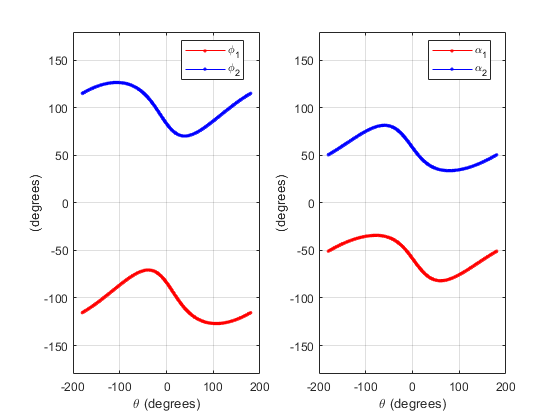

LOC_plot_stuff(my)

## Explore the angular relationships

What happens when we specify a machine which simply can't be configured ?  

### **Case_1:   a ridiculous INVALID machine  **

- $L_1 =1,{\;\;\;L}_2 =2,\;\;\;L_3 =3$ and a ridiculous value of $L_4 =100\;\;$

Clearly this machine canNOT be realised. 

%[the_z,~,~] = bh_z_func(L_1, L_2, L_3,  L_4, theta)
 [the_z,~,~] = bh_z_func(  1,   2,    3, 100,  0)

the_z =    0.0000 + 1.0625i
   0.0000 - 1.0625i


Note the COMPLEX values for $z_1$ and $z_2$.  For this particular machine there are NO input angles that result in a valid pose - the machine simply is an INVALID machine.  Another interesting case is when we have the output link acting as a Rocker, ie:

### **Case_2:  A ROCKER machine**

-   
$$L_1 =1\ldotp 2,{\;\;\;L}_2 =1\ldotp 4,\;\;\;L_3 =0\ldotp 4,\;\;L_4 =1$$


When $\theta ={60}^{\;\circ }$, the machine is valid, ie:  here are the 2 valid poses   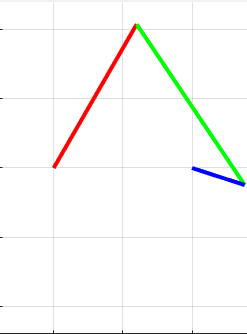      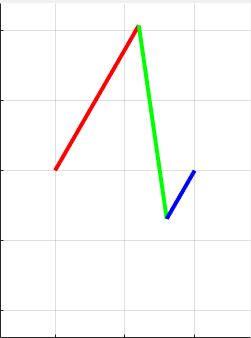

 [the_z,~,~] = bh_z_func(  1.2, 1.4, 0.4, 1, pi/3 )

the_z =    -1.7321
   -0.1575


But clearly this ***same*** machine can NOT be configured for say $\theta ={0\;}^{\circ }$

  [the_z,~,~] = bh_z_func(  1.2, 1.4, 0.4, 1, 0)

the_z =    0.0000 - 1.0954i
   0.0000 + 1.0954i


### **Case_3:  a machine with some kinematic SINGULARITY poses**

-   
$$L_1 =L_3 \;=\;0\ldotp 2,{\;\;\;\;\textrm{and}\;\;\;\;\;\;L}_2 =L_4 \;=1$$


When $\theta ={60}^{\;\circ }$, the machine is valid, ie:  here are the 2 valid poses

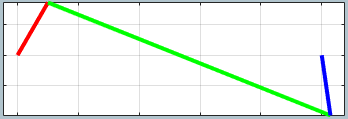 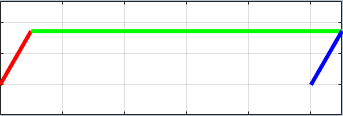

[the_z,~,~] = bh_z_func(  0.2, 1, 0.2, 1, pi/3)  

the_z =    -0.8660
    0.5774


But when $\theta ={0\;}^{\circ }$, our mathematical description has a singularity for this specific pose - ***OR so it would seem !!***

[the_z,the_num,the_den] = bh_z_func(  0.2, 1, 0.2, 1, 0)  

the_z = 	1.0e+-7 *

   0.0000 - 0.1473i
   0.0000 + 0.1473i


the_num = 	1.0e+-8 *

   0.0000 + 0.9424i
   0.0000 - 0.9424i


the_den =    -0.6400
   -0.6400


In the above example, the machine really can be placed in that pose (ie $\theta ={0\;}^{\circ }$) .... but what you're seeing is the result of machine precision used in the floating point arithmatic.  Recall that the expressions for the roots for $z_1 \;\textrm{and}\;z_2$ involve a square root, and what we've stumbled upon here is a case where instead of finding the root of ZERO .... our floating point arithmatic caused a square root of a very small NEGATIVE number.  We can correct for these cases, eg: see the function `bh_z_calc_util.m.`

Another example of a **mathematical  singularity **occurs for the machine $L_1 =L_3$ and $L_2 =L_4$, and when we place it in the pose $\theta ={\mp 180\;}^{\circ }$ we see that our $z$ roots are non finite

[the_z,~,~] = bh_z_func(  0.2, 1, 0.2, 1,  pi) 

the_z = 	1.0e+08 *

   0.0000 + 1.6977i
   0.0000 - 1.6977i


[the_z,~,~] = bh_z_func(  0.4, 1, 0.4, 1, -pi) 

the_z =    Inf
  -Inf


To see what's causing this, see the script file:

- `bh_explore_Singularities.mlx`

- `bh_explore_Singularities_part_2.mlx`

# The 4bar class `bh_4bar_kin_z_analysis_CLS`

To simplify the exploration of the 4bar mechanism, a simple MATLAB class called `bh_4bar_kin_z_analysis_CLS` has been developed.  A typical usage workflow looks like this:

The above usage workflow will allow you to see the "valid" poses that the machine can be configured to.  You can then plot the machine in a specific pose by specifying the input angle $\theta$ in radians, ie:

Let's explore the use of this class (and the 4bar mechanism) in the examples below.

## Explore the angular relationships - Part 1, a full crank rotation machine

So let's look at some plots for specific values of $\left\lbrace L_1 ,L_2 ,L_3 ,L_4 ,\theta \;\right\rbrace$

clear my_numeric

my_numeric.L1 = 0.4;
my_numeric.L2 = 1.4;
my_numeric.L3 = 1.2;
my_numeric.L4 = 1;
my_numeric.theta_rad = pi/3;

Let's plot the machine - NOTE the 2 possible machine configurations, which correspond to the $z_1$ and $z_2$ roots discussed earlier.

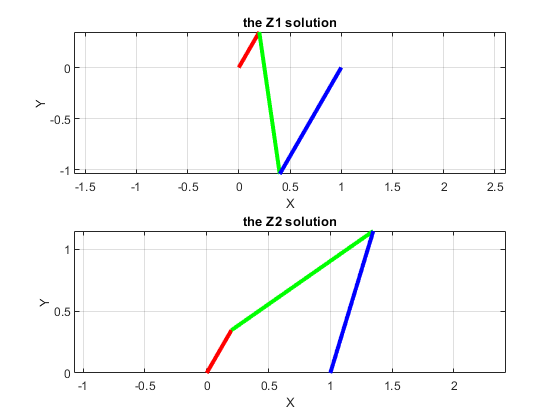

OBJ_kin = bh_4bar_kin_z_analysis_CLS(my_numeric.L1, my_numeric.L2, ...
                                     my_numeric.L3, my_numeric.L4, my_numeric.theta_rad);
OBJ_kin.plot();

For this **specific** machine we can also view the angles:

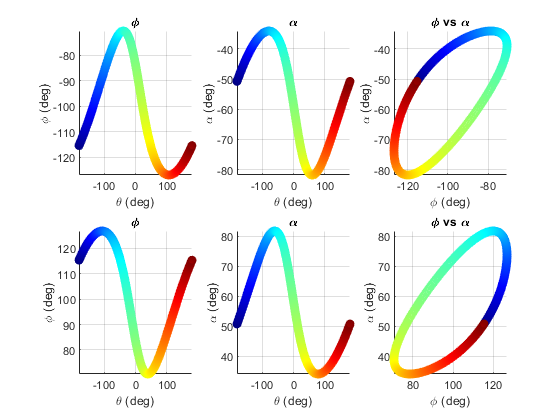

OBJ_kin.plot_angles_flat()

and another way of viewing the angles:

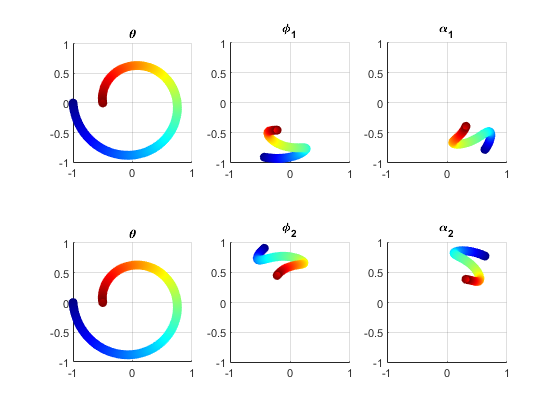

OBJ_kin.plot_angles_round();

## Explore the angular relationships - Part 2, a LIMITED crank rotation machine

Let's look at another machine characterised by specific values of $\left\lbrace L_1 ,L_2 ,L_3 ,L_4 ,\theta \;\right\rbrace$

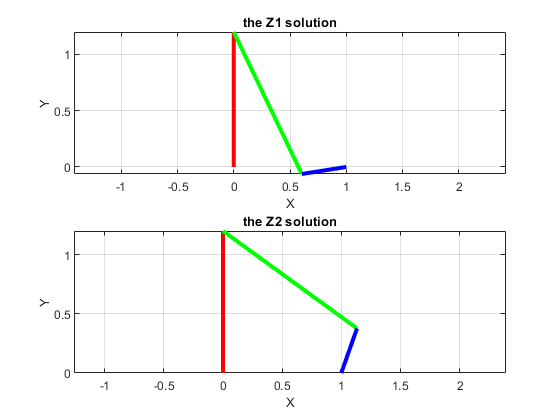

my_numeric.L1 = 1.2;
my_numeric.L2 = 1.4;
my_numeric.L3 = 0.4;
my_numeric.L4 = 1;
my_numeric.theta_rad = pi/2;

OBJ_kin = bh_4bar_kin_z_analysis_CLS(my_numeric.L1, my_numeric.L2, ...
                                     my_numeric.L3, my_numeric.L4, my_numeric.theta_rad);
OBJ_kin.plot();

So let's have a look at the values of $\theta$ that produce REAL values for $z$ (and therefore real values for $\phi$ and $\alpha$):

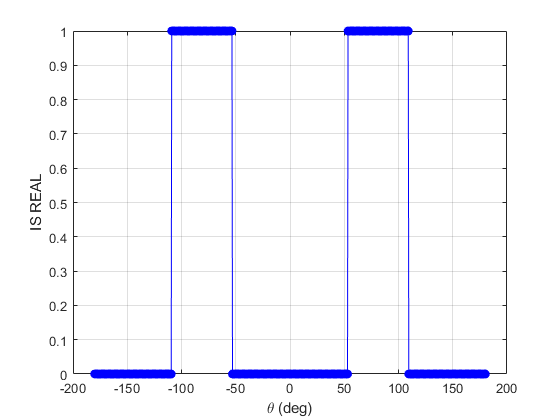

[z_pair_mat, theta_deg_col, tf_is_real] = OBJ_kin.calc_z_values();

figure;
    plot(theta_deg_col, double(tf_is_real), '-bo');
        xlabel("\theta (deg)"); ylabel("IS REAL");
        grid('on')

So the machine has 2 ranges of $\theta$ that the machine can be configured to, ie:

- 
$$-109\le \;\theta \le -54$$


- 
$$\;\;\;\;\;\;54\le \;\theta \le 109$$


and we can see this also from the plots below:

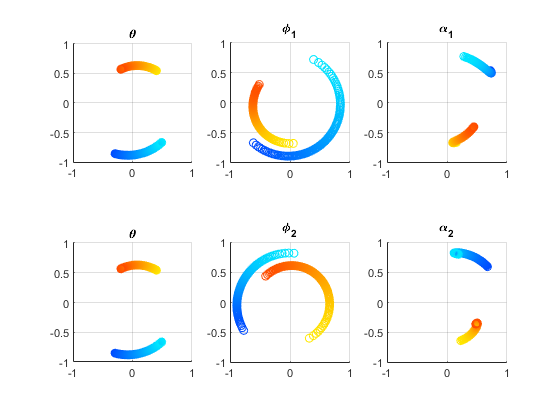

OBJ_kin.plot_angles_round();

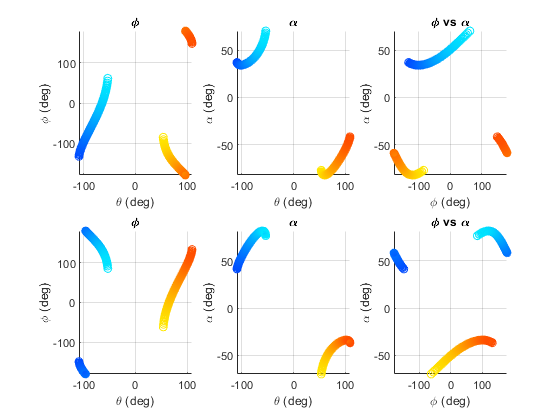

OBJ_kin.plot_angles_flat();

## Explore the angular relationships - Part 3, the $\phi$ positive solution

For convenience, when we have a rocker machine, usually we'll look at a machine where the $\phi$ angle is positive, eg:

my_numeric.L1 = 0.4;
my_numeric.L2 = 1.4;
my_numeric.L3 = 1.2;
my_numeric.L4 = 1;
my_numeric.theta_rad = pi/3;

OBJ_kin = bh_4bar_kin_z_analysis_CLS(my_numeric.L1, my_numeric.L2, ...
                                     my_numeric.L3, my_numeric.L4, my_numeric.theta_rad);

View the machine for the configuration where the $\phi$ angle is positive

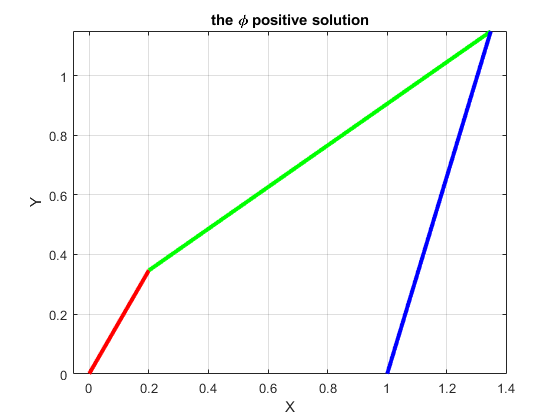

OBJ_kin.plot_phi_pos();

Extract the link angles $\phi$ and $\alpha$ :

[phi_rad, alpha_rad] = OBJ_kin.get_phi_alpha(my_numeric.theta_rad);

Echo the angles in degrees:

table( rad2deg([my_numeric.theta_rad; phi_rad; alpha_rad]) , ...
               'RowNames',["Theta", "Phi", "Alpha"], ...
                'VariableNames', "Angles_DEGREES")

ans = 3×1 table
             Angles_DEGREES
             ______________

    Theta            60    
    Phi          73.174    
    Alpha         34.96    


# Next steps (part 1) - The 4bar **App**

You can explore even more examples of 4bar linkages using the app:

- `>> bh_4bar_explore_app`

This app allows you to visualize VALID machines - see the discussion `here` for what we mean by a VALID machine.

You can use the APP to see animations of the machines.

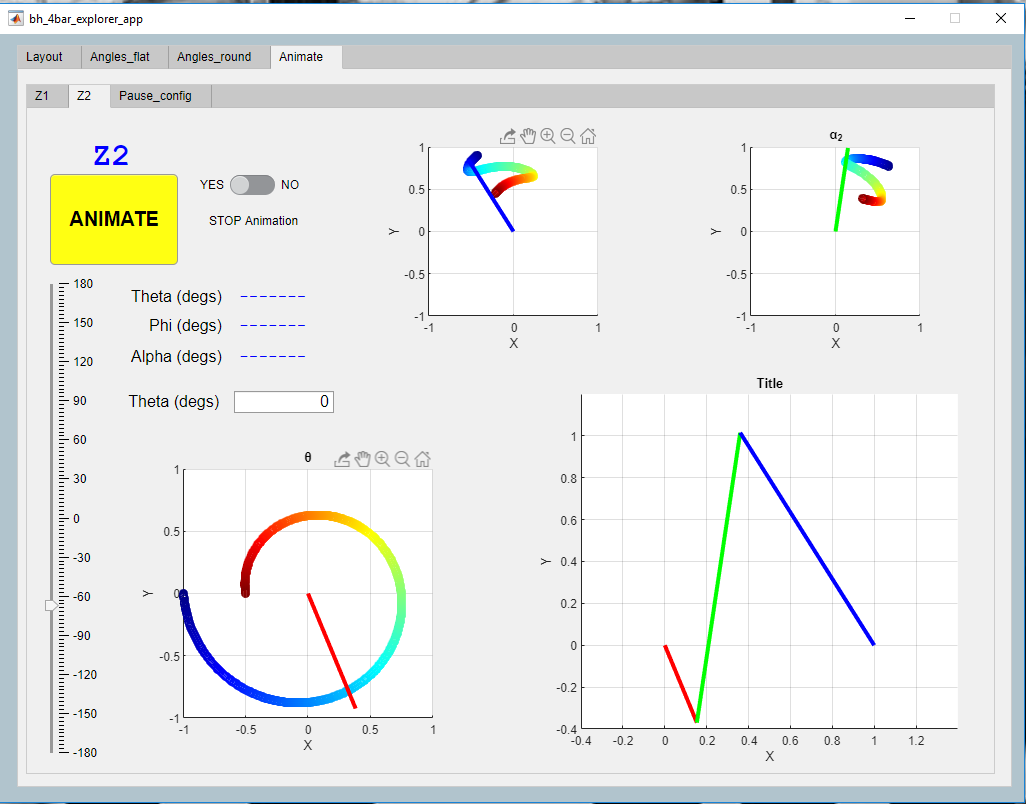

# Next steps (part 2) - a kinematic model in **Simulink**

Having derived the kinematic equations for the 4bar mechanism, we can use Simulink(more specifically Simscape) to animate a given machine.

So NEXT steps will be

- Open the script called `DEMO_03a_bh_4bar_KIN_sim.mlx`

- Run the script and explore the Simulink model `bh_4bar_model_KIN.slx`

- Run the Simulink model `bh_4bar_model_KIN.slx`

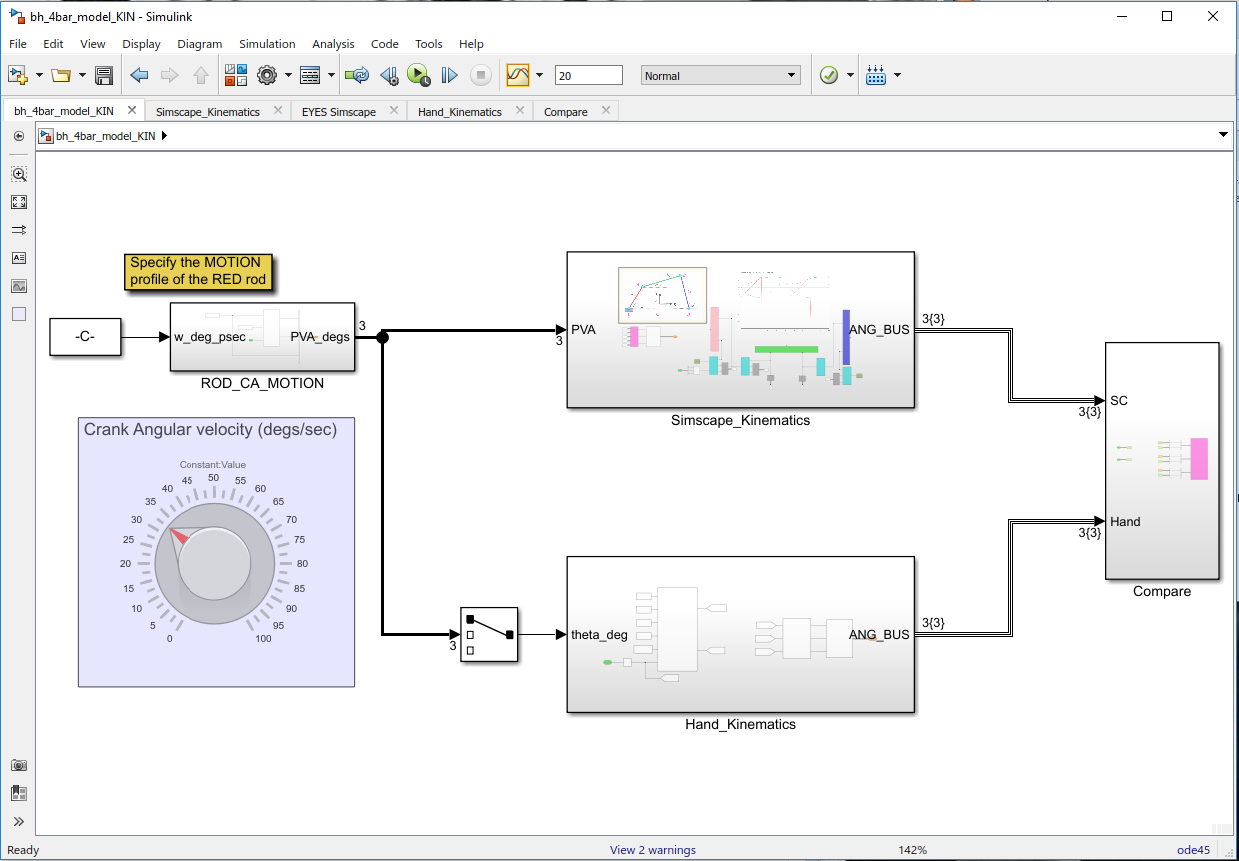   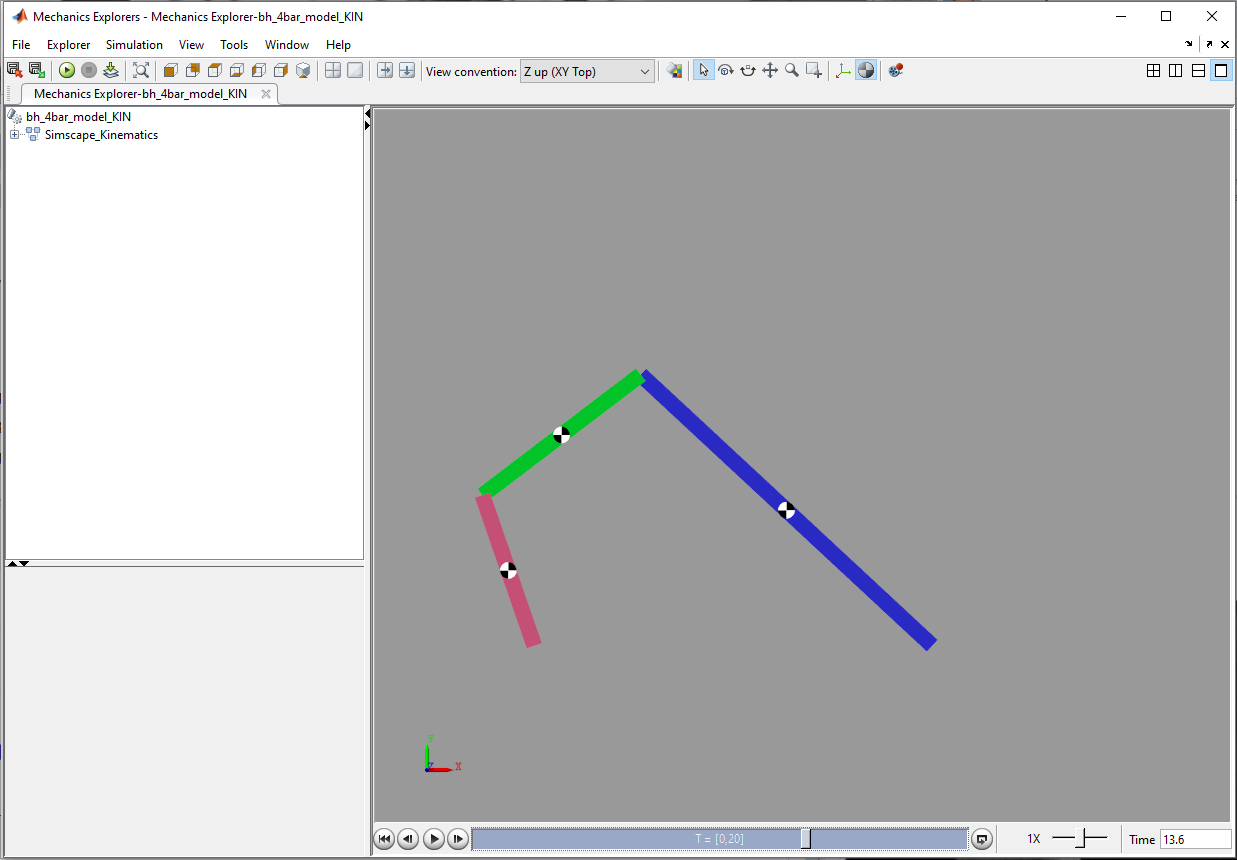

# Helper Functions

Let's produce MATLAB functions from our symbolic expressions:

function LOC_create_MATLAB_functions(the_z, phi_sol_1, phi_sol_2, alpha_sol)
    
    syms L_1   L_2  L_3  L_4  theta phi
        
    [N1,D1] = numden( the_z(1) );
    [N2,D2] = numden( the_z(2) );
    
    the_num = [N1;N2];
    the_den = [D1;D2];
    
    f_z = matlabFunction( the_z, the_num, the_den, ...
                                 'File', 'bh_z_func', 'Vars', [L_1, L_2, L_3, L_4, theta]);    
    f_phi_1 = matlabFunction( phi_sol_1, ...
                                 'File', 'bh_phi_1_func', 'Vars', [L_1, L_2, L_3, L_4, theta]);
    f_phi_2 = matlabFunction( phi_sol_2, ...
                                 'File', 'bh_phi_2_func', 'Vars', [L_1, L_2, L_3, L_4, theta]);                         
    f_alpha = matlabFunction( alpha_sol, ...
                                 'File', 'bh_alpha_func', 'Vars', [L_1, L_2, L_3, L_4, theta, phi]);  
    
end

**A plotting utility:**

function LOC_plot_stuff(my)

    % Convert RADIANS to DEGREES    
    phi_1   = rad2deg(my.phi_1_rad_vec);
    alpha_1 = rad2deg(my.alpha_1_rad_vec);
    phi_2   = rad2deg(my.phi_2_rad_vec);
    alpha_2 = rad2deg(my.alpha_2_rad_vec);    
    
    % wrap degrees to the range [-180, 180]
    phi_1   = bh_wrap_DEG_angles(phi_1,   "-180_TO_180");
    phi_2   = bh_wrap_DEG_angles(phi_2,   "-180_TO_180");
    alpha_1 = bh_wrap_DEG_angles(alpha_1, "-180_TO_180");
    alpha_2 = bh_wrap_DEG_angles(alpha_2, "-180_TO_180");    

    % now plot stuff
    figure;
    hax(1) = subplot(1,2,1);  plot(my.theta_deg_vec, phi_1,   '-r.'); grid('on'); 
    hax(2) = subplot(1,2,2);  plot(my.theta_deg_vec, alpha_1, '-r.'); grid('on');  
    
    hold(hax(1),'on');        plot(hax(1),my.theta_deg_vec, phi_2,   '-b.'); 
    hold(hax(2),'on');        plot(hax(2), my.theta_deg_vec, alpha_2, '-b.'); 
    
    for kk=1:2
       xlabel(hax(kk), '\theta (degrees)');
       ylabel(hax(kk), '(degrees)');
       
       ylim(hax(kk), [-180, 180]);
    end
    
    legend(hax(1), {  '\phi_1',   '\phi_2'},  'Location','best');
    legend(hax(2), {'\alpha_1', '\alpha_2'},  'Location','best');   
   
end